Polynomial Approximation

clear all
close all
% Data points
n = 6; % n -1 order polynomial
h = 0.1; %step
X = 0 : h : 10;

SDP solution with constraints

% variables to find
t = sdpvar(1);
a = sdpvar(1,n);
y = sdpvar(1,length(X));
% objective function
F = t

Linear scalar (real, 1 variable)
Coefficients range: 1 to 1


% constructing LMI
S = [];
for i = 1 : length(X)
S = [S; a*getPowers(X(i)) - y(i)]; % preallocate for speed
end
LMI = [eye(length(X)) S;
      S'  t ];
constr = [LMI >=0; y <= 5; y >= 0; y(1) <= 1; y(31) >= 4; y(71) <= 1; y(101) <= 3; y(101) >= 2];
opts = sdpsettings('solver', 'sdpt3', 'sdpt3.maxit', 50);
optimize(constr, F, opts);


 num. of constraints = 108
 dim. of sdp    var  = 102,   num. of sdp  blk  =  1
 dim. of linear var  = 207
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.6e+01|8.4e+04|4.6e+09| 2.480459e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.977|0.004|1.3e+00|8.4e+04|4.8e+09| 1.023776e+07 -1.764304e+03| 0:0:00| chol  1  1 
 2|1.000|0.973|5.2e-04|2.3e+03|1.4e+08| 9.799737e+06 -2.268407e+05| 0:0:00| chol  1  1 
 3|1.000|0.989|8.6e-05|2.5e+01|2.7e+06| 1.242497e+06 -2.544304e+03| 0:0:00| chol  1  1 
 4|0.989|0.989|2.3e-06|2.9e-01|4.1e+04| 2.470910e+04 -3.583019e+01| 0:0:01| chol  2  2 
 5|0.973|1.000|1.5e-05|3.8e-03|4.6e+03| 4

coeffs = value(a);
dataPoints = value (y);

Plotting Polynom

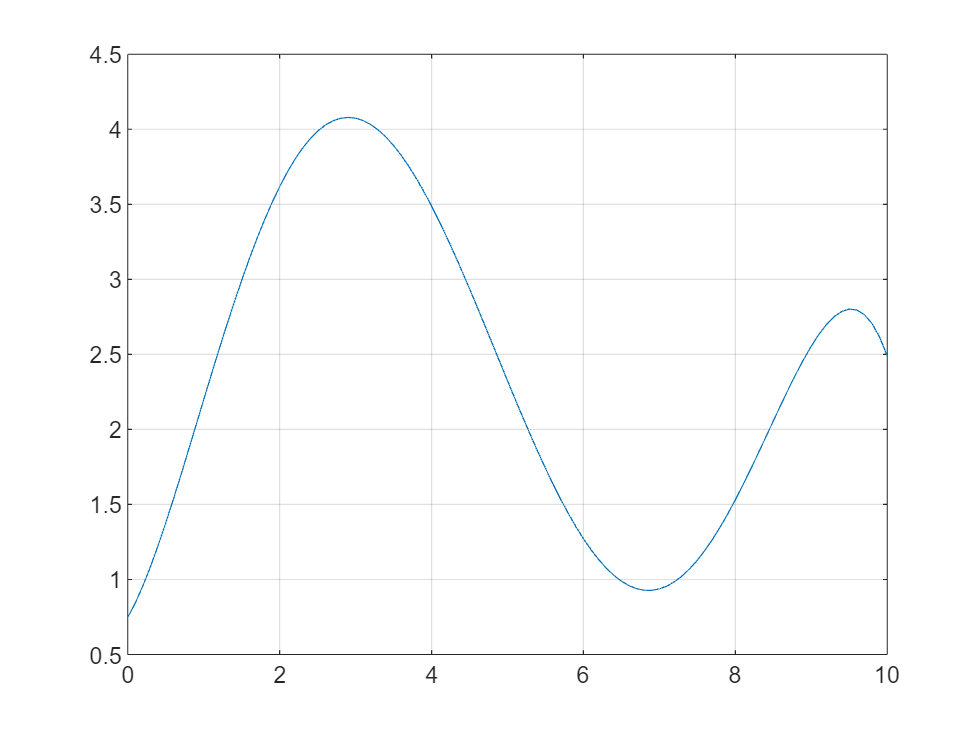

figure
plot(X, dataPoints)
grid on

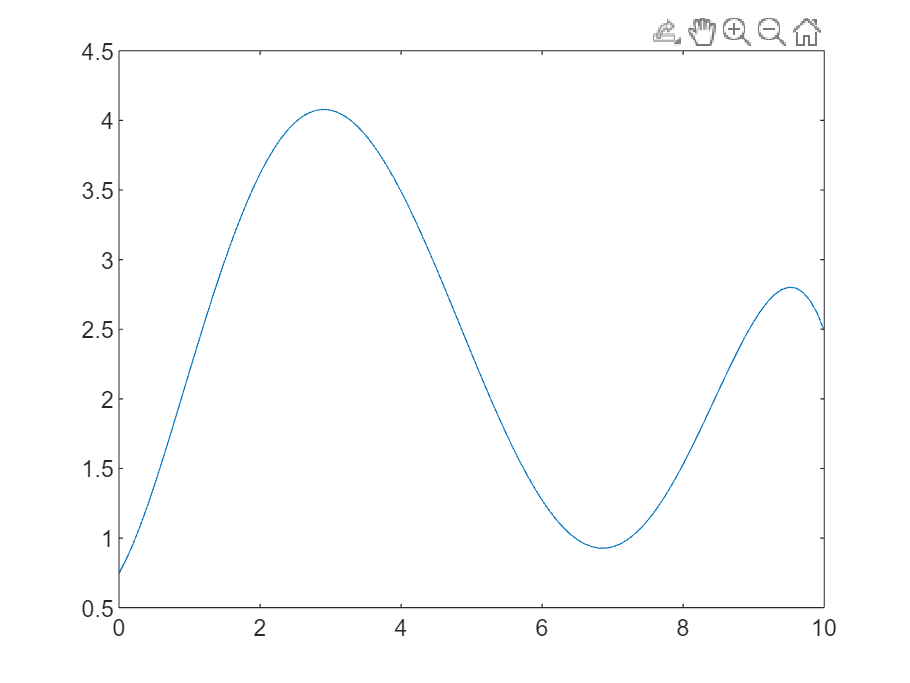

poly = wrev(coeffs);
y1 = polyval(poly, X);
plot(X, y1)

% check polynom
polyval(poly, X(1))

ans = 0.7470

polyval(poly, X(31))

ans = 4.0740

polyval(poly, X(71))

ans = 0.9369

polyval(poly, X(101))

ans = 2.4894

t1 = value(t) % value of the objective function

t1 = 3.0100e-10

Noisy Polynomial

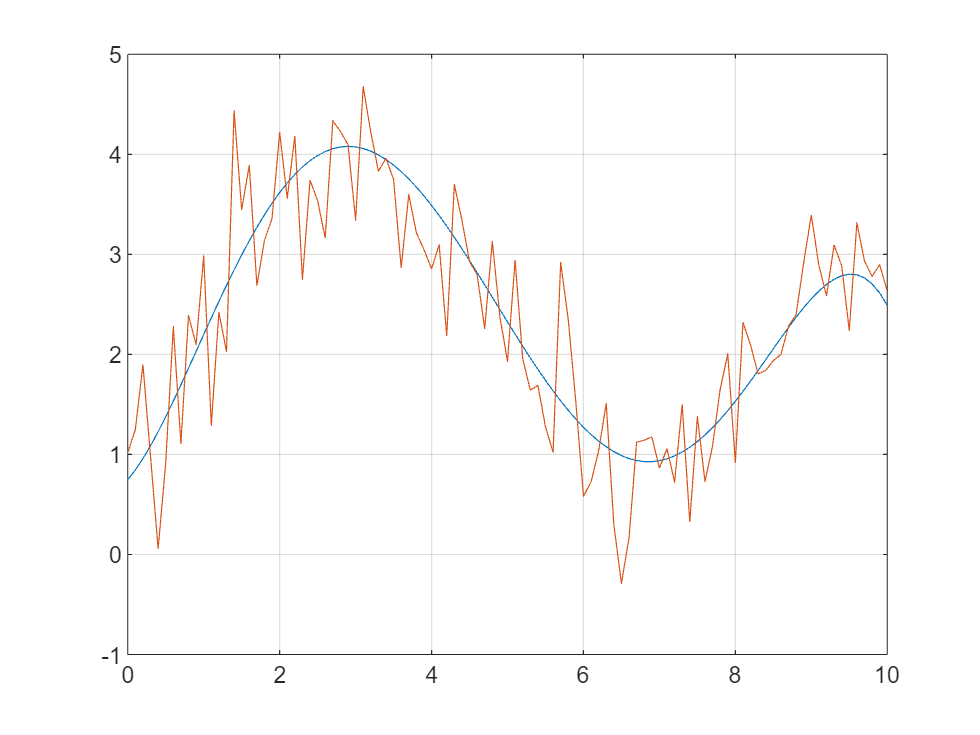

y1noisy = y1 + randn(1, length(y1))*sqrt(0.3);
figure
plot(X, y1)
grid on
hold on
plot(X, y1noisy)

Poly Coefficients Recovering using LSR norm

Y = y1noisy;
% variables to optimize
t1 = sdpvar(1);
a1 = sdpvar(1, n);
% objective function
F1 = t1;
% constructing LMI
S1 = [];
for i = 1 : length(X)
S1 = [S1; a1*getPowers(X(i)) - Y(i)]; % preallocate for speed
end
LMI = [eye(length(X)) S1;
      S1'  t1 ];

constr1 = LMI >=0; % constraints for optimization 
opts1 = sdpsettings('solver', 'sdpt3', 'sdpt3.maxit', 80);
optimize(constr1, F1, opts1);


 num. of constraints =  7
 dim. of sdp    var  = 102,   num. of sdp  blk  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.1e+01|1.1e+05|4.6e+09| 1.030200e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.999|0.989|5.6e-02|1.2e+03|5.0e+07| 1.030194e+04 -4.249310e+05| 0:0:00| chol  1  1 
 2|1.000|0.989|1.1e-06|1.3e+01|5.5e+05| 1.029724e+04 -8.862863e+03| 0:0:00| chol  1  1 
 3|1.000|0.986|3.3e-07|1.9e-01|1.7e+04| 9.896201e+03 -1.239014e+02| 0:0:00| chol  1  1 
 4|1.000|0.986|2.6e-08|4.8e-03|2.2e+03| 2.096989e+03 -3.055832e+01| 0:0:00| chol  1  1 
 5|0.984|0.974|4.8e-10|3.3e-04|3.5e+01| 6.372911e+00 -2.886619e+01| 0

coeffs1 = value(a1);

coeffs1 =     0.9353    0.6985    0.9983   -0.4606    0.0616   -0.0026


Comparing original poly with recovered

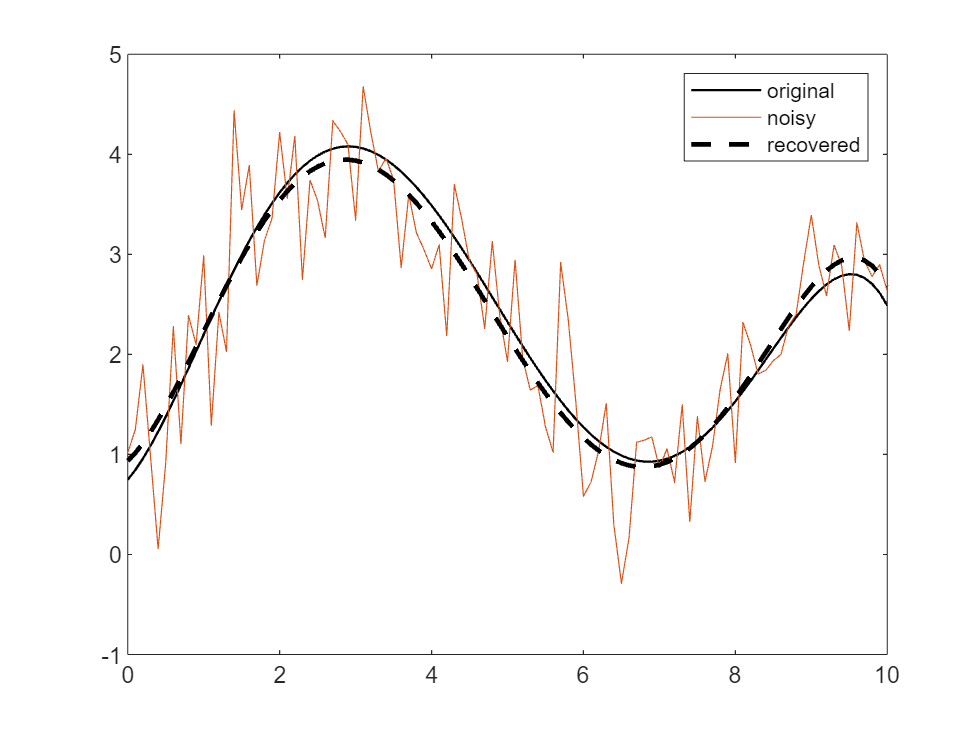

poly1 = wrev(coeffs1);
y1rec = polyval(poly1, X);

figure
plot(X, y1,'-k',LineWidth=1) % original polynom
hold on
plot(X, y1noisy) % polynom with noise
hold on
plot(X, y1rec,'--k',LineWidth=2) % recovered polynom
legend("original", "noisy", "recovered")

function vec = getPowers(x)
    vec = [1 ; x; x.^2; x.^3; x.^4; x.^5];
end